# Assignment 1

## Data Processing

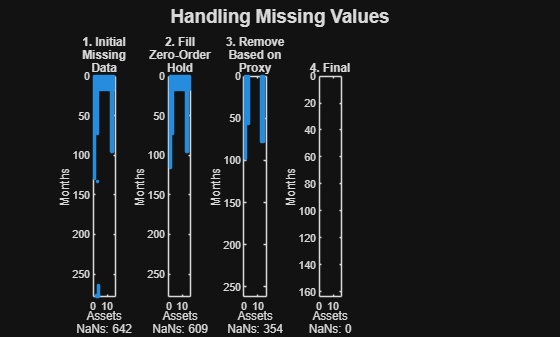


% 0. Clear environment and remove all plots
clc % clears the command window
close all %removes all figures
clear % clears the workspace

% 1. Load the data
% 1.1 Loading the excel file into matlab
fileName =  "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx";
excelSheetNames = sheetnames(fileName);
% 1.2 Preallocate cell array before looping
data{numel(excelSheetNames)} = [];
% 1.3 Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
    data{sheet} = readtimetable(fileName, 'Sheet', excelSheetNames{sheet}, 'VariableNamingRule', 'preserve');
end

% 2. Filter and Clean Data: Keep Only Relevant Tickers and Columns
% 2.1 Define a list of all the assets we want to include in the universe
%      - Includes RATESTEFI, ALBI, key J-bonds, variable J5x tickers, and major JSE indices
variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'RATEJ2Y4', 'ALBI', 'J203', 'J500', 'J330', 'J331', variableTickers{:}};
% 2.2 Loop over each sheet in the dataset
for i = 1:numel(data)
    % 2.2.1 Keep only TRI (Total Return Index) columns for sheets 3 and 4
    if i == 3
        allVarTable = data{i}; 
        TRITable = allVarTable(:, (3:3:27));   % select every 3rd column (TRI)
        TRITable = TRITable(4:end,:);          % remove the first 3 rows (NaNs)
        % Convert all columns to numeric if they are cells/strings 
        % (i.e. J500 needs converting)
        for col = 1:width(TRITable)
            colName = TRITable.Properties.VariableNames{col};
            % Check if the column is cell or string
            if iscell(TRITable.(colName)) || isstring(TRITable.(colName))
                TRITable.(colName) = str2double(TRITable.(colName));  % convert to numeric
            end
        end
        data{i} = TRITable;
    elseif i == 4
        allVarTable = data{i};
        allVarTable = removevars(allVarTable, ["SOURCE68779","Var2"]); % remove unwanted columns
        TRITable = allVarTable(:, (4:4:19));   % select every 4th column (TRI)
        TRITable = TRITable(4:end,:);           % remove the first 3 rows (NaNs)
        data{i} = TRITable;
    else
        % 2.2.2 For other sheets, just skip the first 3 rows
        data{i} = data{i}(4:end, :);  
    end
    % 2.3 Match column names to entities (whitelist)
    opts = data{i}.Properties;                  % get table properties
    variableMatch = zeros(size(opts.VariableNames));  % preallocate array for matching
    % 2.3.1 Perform string comparison for column matching
    if i == 2 
        % Sheet 2: compare first 8 characters to avoid unwanted matches
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 8)) = k;
        end
    else
        % Other sheets: compare first 4 characters
        for k = 1:numel(entities)
            variableMatch(strncmp(opts.VariableNames, entities{k}, 4)) = k;
        end
    end
    % 2.3.2 Identify and remove columns not in the whitelist
    idx = find(variableMatch == 0);                    % find unwanted tickers
    tickersToBeRemoved = opts.VariableNames(idx);      % get their names
    data{i} = removevars(data{i}, tickersToBeRemoved); % remove them from the table
    % 2.4 Clean up remaining column names
    %      - Remove any text after ':' to simplify variable names
    hasColon = contains(data{i}.Properties.VariableNames, ':');     
    data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon), ':');
end

% 3. Clean and convert into a single timetable
allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','RATEJ2Y4','J203'}, {'STEFI','JIBAR','ALSI'});

% 4. Down-sample (by decimation)
% 4.1 Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable); % Home -> Add-ons -> Financial Toolbox

% 5. Visualising and Handling Missing Data
% Helper function to get number of NaNs
countNaNs = @(T) sum(isnan(table2array(T)),'all');
% 5.1 Initial Missing Data Visualisation
figure;
subplot(1,6,1);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"1. Initial","Missing","Data"})
% 5.2  Fill Missing Data with Zero-Order Hold (Last Observation Carried Forward)
allDataTable = fillmissing(allDataTable,'previous');
subplot(1,6,2);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"2. Fill","Zero-Order","Hold"})
% 5.3 Remove Rows Using the Asset With The Least NaN's (best proxy asset)
[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy = allDataTable.Properties.VariableNames{idx}; % Find the column with the FEWEST missing values
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy); % Remove rows where the proxy has NaNs
subplot(1,6,3);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title({"3. Remove","Based on","Proxy"})
% 5.5 Remove Leading Rows with Missing Data
% Detect rows at the start of the dataset that contain NaNs and trim them
idx = isnan(allDataTable{:,:});
allDataTable = allDataTable(max(find(idx,max(max(cumsum(idx)))))+1:end,:);
subplot(1,6,4);
spy(isnan(table2array(allDataTable)));
xlabel(["Assets","NaNs: " + countNaNs(allDataTable)]);
ylabel("Months")
title("4. Final")
sgtitle('Handling Missing Values', 'FontSize', 14, 'FontWeight', 'bold');

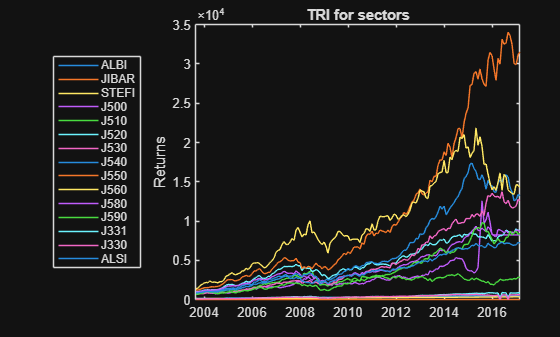


% 6. Visualise the data and the returns on a single plot
% 6.1 Compute simple returns (Rt = (Pt - Pt-1)/Pt-1)
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple');
% 6.2 Plot of the time series
figure;
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
title("TRI for sectors")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

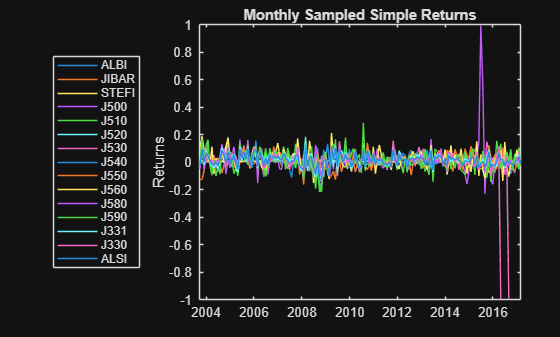

% 6.3 Plot of returns
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")

% 6.4 Handle outlier (J330 and J331)
outlierIdx = allDataReturnsTable.("J330") < -0.5;
outlierRows = find(outlierIdx); 
disp(table( ...
    outlierRows, ...
    allDataReturnsTable.Time(outlierRows), ...
    allDataReturnsTable.("J330")(outlierRows), ...
    allDataReturnsTable.("J331")(outlierRows), ...
    'VariableNames', {'RowIndex', 'Date', 'J330_Return', 'J331_Return'})); % Display the outliers

    RowIndex       Date        J330_Return    J331_Return
    ________    ___________    ___________    ___________

      152       30-Apr-2016        -1             -1     
      156       31-Aug-2016        -1             -1     



allDataReturnsTable.("J330")(outlierIdx) = NaN; % set the outliers to NaN
allDataReturnsTable.("J331")(outlierIdx) = NaN; % set the outliers to NaN
% Check J500
outlierIdx2 = allDataReturnsTable.("J500") > 0.5;
outlierRows2 = find(outlierIdx2); 
disp(table( ...
    outlierRows2, ...
    allDataReturnsTable.Time(outlierRows2), ...
    allDataReturnsTable.("J500")(outlierRows), ...
    'VariableNames', {'RowIndex', 'Date', 'J500_Return'}));

    RowIndex       Date        J500_Return
    ________    ___________    ___________

      142       30-Jun-2015         0     
      143       31-Jul-2015         0     



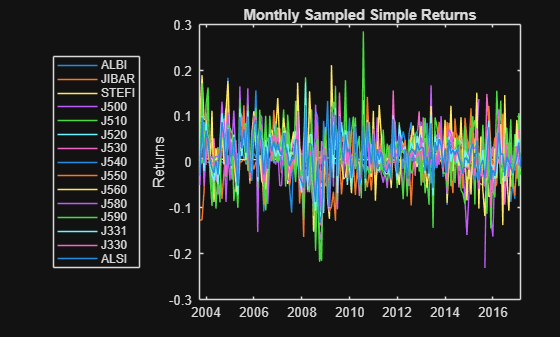

allDataReturnsTable.("J500")(outlierIdx2) = NaN;
% 6.5 Plot of returns without the outliers
figure;
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
legend(allDataTable.Properties.VariableNames,Location="westoutside")


% 7. Manage Missing Data
% 7.1 Check if there is still missing data or cells of zero
any(isnan(allDataReturnsTable{:,:}))

ans = 1×15 logical array
   0   0   0   1   0   0   0   0   0   0   0   0   1   1   0


nZeros = sum(allDataTable{:,:} == 0,'all');
disp(['Total zero values: ', num2str(nZeros)]);

Total zero values: 4


% 7.2 Compute the Arithmetic means correcting for missing data (NAN)
portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');
% 7.3 Fill those missing values with the previous results
allDataTable{:,:}(allDataTable{:,:} == 0) = NaN; % Replace zeros with NaN
allDataTable = fillmissing(allDataTable,'previous'); % Replace NaNs with the previous observation

### Jibar 3 Month Yield (Close)

% 8. Discounting the 3 month jibar yield
threeMonthJibar = allDataTable{:, 'JIBAR'};

% Convert 3-month JIBAR to monthly equivalent
monthlyJibar = (1 + threeMonthJibar).^(1/3) - 1;

% Update the table with the monthly JIBAR values
allDataTable{:, 'JIBAR'} = monthlyJibar;
mean(monthlyJibar)

ans = 1.0150

## Experiment 1

### Set Up

% 1. Split into two sets of data
% 1.1 Number of observations
nObs = size(allDataTable,1);
% 1.2 Choose a split point (e.g. 70% training, 30% test)
splitPoint = floor(0.7 * nObs);
% 1.3 Also keep the dates if you need them
train = allDataTable(1:splitPoint,:);
test  = allDataTable(splitPoint+1:end,:);
disp(['Training rows: ', num2str(size(train,1))]);

Training rows: 114


disp(['Test rows: ', num2str(size(test,1))]);

Test rows: 49


returnType = "continuous";
tickers = setdiff(train.Properties.VariableNames,{'STEFI','JIBAR','ALSI','J330','J331'}); % Tickers to include
riskFreeTicker = "STEFI";

### Training

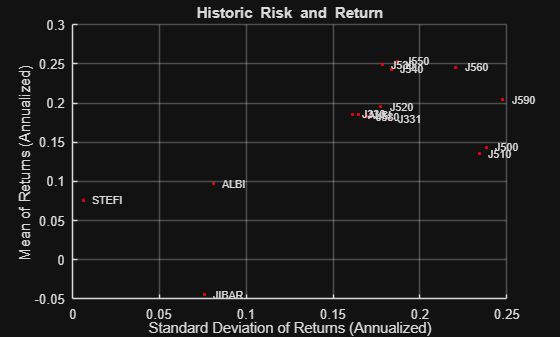

% 2.1 Portfolio Set Up
q = Portfolio('AssetList',train.Properties.VariableNames);
% 2.2 Simple Arithmetic Returns
trainReturnsTable = tick2ret(train,'Method',returnType); % Change this if needed
q = estimateAssetMoments(q,trainReturnsTable{:,:});
% 2.3 Visualise the Risk-Return Relationship
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Fully invested portfolio with varying risk aversion (efficientFrontier1)

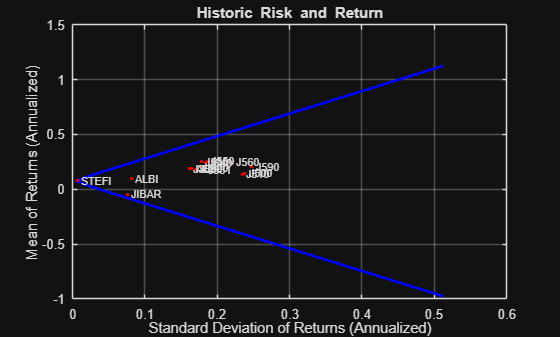

% 3. Fully invested portfolio with varying risk aversion 
function [PortWts, ret, rsk] = efficientFrontier1(q, lambda)
    % 3.1 Fully Invested
    q.AEquality = ones(1,length(q.AssetMean));
    q.bEquality = 1;
    PortWts = NaN(length(lambda),length(q.AssetMean));
    
    % 3.2 Find the optimal portfolio weights
    options = optimoptions('quadprog','Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
        H = q.AssetCovar; %the covariance matrix
        PortWts(i,:) = quadprog(H, f, [], [], q.AEquality, q.bEquality, [], [], [], options) ;
    end
    % 3.3 Compute Portfolio Risk and Return
    ret = estimatePortReturn(q, PortWts');
    rsk = estimatePortRisk(q,PortWts');
    %ret = PortWts * q.AssetMean';
    %rsk = sqrt(diag(PortWts * q.AssetCovar * PortWts'));
end

% 3.4 Efficient Frontier
% Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);
[Wts,ret1,rsk1] = efficientFrontier1(q,lambda);
% 3.5 Plot the Curve
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk1, ret1}, ...
	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow$Excluding Cash and Market Indices (efficientFrontier2)

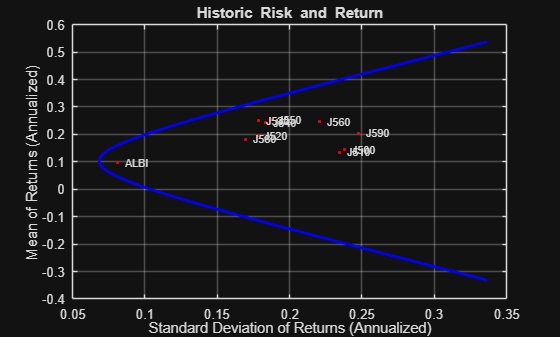

% 4. Exclude the Cash and Market Indices
function [PortWts, ret, rsk] = efficientFrontier2(trainReturnsTable, lambda, includingTickers)
    % 4.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 4.2 Fully Invested
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(lambda),length(mu));
    
    % 4.3 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,[],[],[],optionsQP);
    end
    
    % 4.4 compute risk and return 
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 4.5 Efficient frontier
% Tickers we are excluding 
lambda = linspace(-0.25,0.25,45);
[Wts, ret2,rsk2] = efficientFrontier2(trainReturnsTable,lambda,tickers );

%  4.6 Plot
plotIdx = ismember(q.AssetList, tickers);
clf;
portfolioexamples_plot('Historic Risk and Return', ...
	{'line', rsk2, ret2}, ...
    {'scatter', sqrt(diag(q.AssetCovar(plotIdx,plotIdx))), q.AssetMean(plotIdx), q.AssetList(plotIdx), '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\Rightarrow \;$No short selling constraint (Method 1: Adjusting Risk Aversion) (efficientFrontier3)

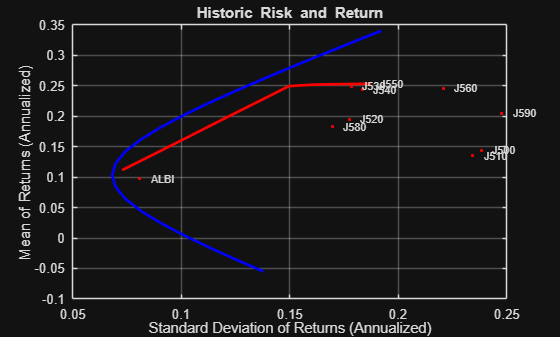

% 5. Exclude the Cash and Market Indices
function [PortWts,ret, rsk] = efficientFrontier3(trainReturnsTable, lambda, includingTickers)
    % 5.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 5.2 Fully Invested (equality constraint)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(lambda),length(mu));
    
    % 5.3 No Short-selling (inequality constraint)
    A = -eye(length(mu));
    b = zeros(length(mu),1);
    
    % 5.4 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(lambda)
        f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,A,b,Aeq,beq,[],[],[],optionsQP);
    end
    
    % 5.5 compute risk and return
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 5.6 Efficient Frontier
% Create the range of risk aversion parameters
lambda = 12*linspace(0,1,25);
[Wts, ret3, rsk3] = efficientFrontier3(trainReturnsTable, lambda, tickers);

% 5.7 Plot
plotIdx = ismember(q.AssetList, tickers);
clf;
portfolioexamples_plot('Historic Risk and Return', ...
    {'line', rsk2(15:end-10), ret2(15:end-10)}, ...
	{'line', rsk3, ret3, '','r'}, ...
    {'scatter', sqrt(diag(q.AssetCovar(plotIdx,plotIdx))), q.AssetMean(plotIdx), q.AssetList(plotIdx), '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### $\iff \;$No short selling constraint (Method 2: Adjusting Required Returns) (efficientFrontier4)

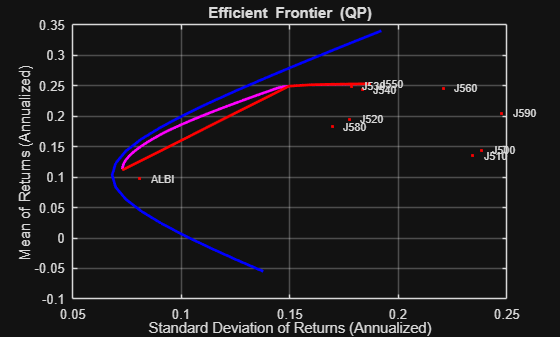

% 6. Exclude the Cash and Market Indices
function [PortWts,ret, rsk] = efficientFrontier4(trainReturnsTable, exceedingValue, includingTickers)
    % 6.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 6.2 Create the range of risk aversion parameters
    retTargetAll = min(mu):((max(mu)-min(mu))/90):max(mu);
    retTarget = retTargetAll(retTargetAll > exceedingValue);
    
    % 6.3 Equality constraint (fully invested)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights
    PortWts = NaN(length(retTarget),length(mu));
    
    % 6.4 No Short-selling (upper and lower bounds)
    ub = ones(length(mu),1);
    lb = zeros(length(mu),1);
    
    % 6.5 Equality constraint (return target)
    Aeq = [Aeq; mu];
    beq = [beq; 0];
    
    % 6.6 Find the optimal portfolio weights
    optionsQP = optimset('quadprog')';
    optionsQP= optimset(optionsQP,'Display','off');
    for i = 1:length(retTarget)
        beq(2) = retTarget(i); % This moves the solution up along the efficient frontier
        H = Sigma; %the covariance matrix
        [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,zeros(size(mu))',[],[],Aeq,beq,lb,ub,[],optionsQP);
    end
    
    % 6.7 compute risk and return
    ret = PortWts * mu';
    rsk = sqrt(diag(PortWts * Sigma * PortWts'));
end

% 6.8 

[Wts, ret4, rsk4 ] = efficientFrontier4(trainReturnsTable,ret3(1),tickers);

%  6.9 Plot
plotIdx = ismember(q.AssetList, tickers);
clf;
portfolioexamples_plot('Efficient Frontier (QP)', ...
    {'line', rsk2(15:end-10), ret2(15:end-10)}, ...
	{'line', rsk4, ret4,'','m'}, ...
	{'line', rsk3, ret3,'','r'}, ...
    {'scatter', sqrt(diag(q.AssetCovar(plotIdx,plotIdx))), q.AssetMean(plotIdx), q.AssetList(plotIdx), '.r'});

%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});


#### $\Rightarrow \;$Maximum Sharpe Ratio Portfolio (maxSharpeRatio)

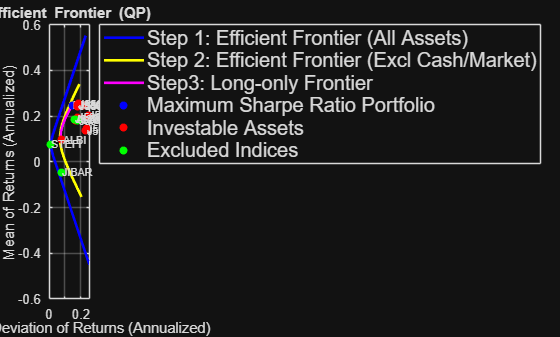

% 7 Exclude the Cash and Market Indices
function [PortWts,ret, rsk, ERFR] = maxSharpeRatio(trainReturnsTable, includingTickers, riskFreeTicker)
    % 7.1 Statistics
    Returns = trainReturnsTable{:,includingTickers};
    mu = mean(Returns); % Use Mean With Excluded Indices
    Sigma = cov(Returns); % Use Covar With Excluded Indices
    
    % 7.2 Risk free rate
    RFR = trainReturnsTable{:,riskFreeTicker};
    % average risk free rate (when to use geometric average)
    ERFR = mean(RFR); 
    
    % 7.3 Equality constraint (fully invested)
    Aeq = ones(1,length(mu));
    beq = 1;
    % initialise the weights for Equally weighted portfolio 
    Wts0 = ones(size(mu))/length(mu);
    
    % 7.4 No Short-selling (upper and lower bounds)
    ub = ones(length(mu),1);
    lb = zeros(length(mu),1);
    
    % 7.5 objective function to maximise the SR
    fn0 = @(x) (-(x*mu' - ERFR)/sqrt(x*Sigma*x'));
    
    % 7.6 Use SQP to solve for the tangency portfolio
    options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8,'Display','off');
    PortWts = fmincon(fn0,Wts0,[],[],Aeq,beq,lb,ub,[],options); % Maximum Sharpe Ratio Portfolio Weights
    
    % 7.7 compute risk and return
    ret = PortWts*mu';
    rsk = sqrt(PortWts*Sigma*PortWts');
end

% 7.8 Tickers we are excluding 
[Wts_train,retSR, rskSR,ERFR_Train] = maxSharpeRatio(trainReturnsTable, tickers, riskFreeTicker);

% 7.9.1 Plot Combined
plotIdx = ismember(q.AssetList, tickers);
excludedIdx = ~plotIdx;
clf; 
portfolioexamples_plot('Efficient Frontier (QP)', ...
    {'line', rsk1(12:end-12), ret1(12:end-12),'','b'}, ...
    {'line', rsk2(10:end-10), ret2(10:end-10),'','y'}, ...
	{'line', rsk4, ret4,'','m'}, ...
    {'scatter', rskSR,retSR,{'Maximum Sharpe ratio'},'b'}, ...
    {'scatter', sqrt(diag(q.AssetCovar(plotIdx,plotIdx))), q.AssetMean(plotIdx), q.AssetList(plotIdx), 'r'}, ... % Investable tickers
    {'scatter', sqrt(diag(q.AssetCovar(excludedIdx,excludedIdx))), q.AssetMean(excludedIdx), q.AssetList(excludedIdx), 'g'}); % Excluded indices in green
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
% Add manual legend outside the plot
hLegend = legend({'Step 1: Efficient Frontier (All Assets)','Step 2: Efficient Frontier (Excl Cash/Market)','Step3: Long-only Frontier',...
    'Maximum Sharpe Ratio Portfolio','Investable Assets','Excluded Indices'}, ...
    'Location','northeastoutside'); % Puts legend outside on the right
set(hLegend,'FontSize',15);

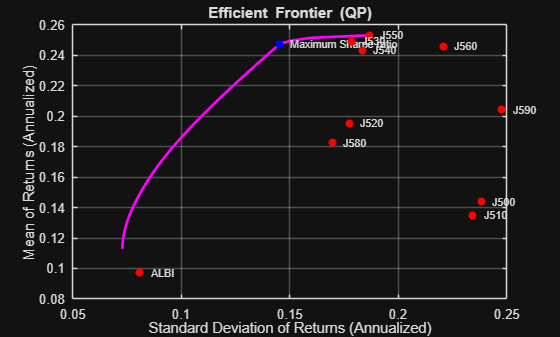

% 7.9.2 Isolated Plot
plotIdx = ismember(q.AssetList, tickers);
clf; 
portfolioexamples_plot('Efficient Frontier (QP)', ...
	{'line', rsk4, ret4,'','m'}, ...
    {'scatter',rskSR,retSR,{'Maximum Sharpe ratio'},'b'}, ...
    {'scatter', sqrt(diag(q.AssetCovar(plotIdx,plotIdx))), q.AssetMean(plotIdx), q.AssetList(plotIdx), 'r'});

#### Market Security Line

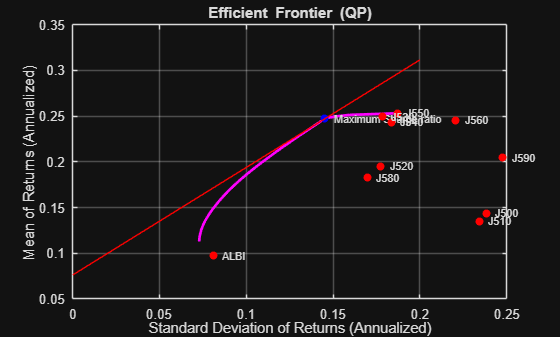

hold on
% 8.1 SML through the tangency portfolio
SML = @(x) (12*ERFR_Train + sqrt(12)*(retSR-ERFR_Train)/rskSR*x);
x = linspace(0,0.20,20);
% 8.2 Plot market line
plot(x,SML(x),'r')
hold off

#### Visualise the Sharpe Ratio Values

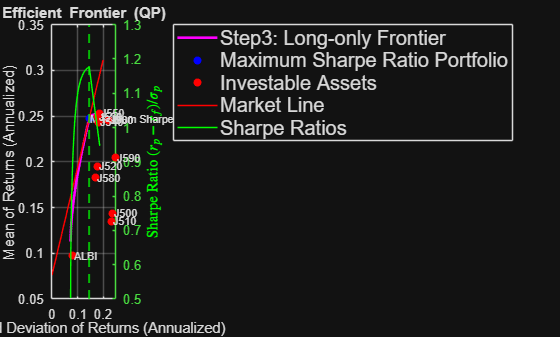


% 9.1 Plot the Sharpe Ratio against risk levels
yyaxis right

% 9.2 plot the Sharpe Ratio against risk level
plot(sqrt(12)*rsk4,sqrt(12)*(ret4-ERFR_Train)./rsk4,'g', 'DisplayName', 'Sharpe Ratio')
xline(rskSR*sqrt(12), '--g', 'LineWidth', 1.5, ...
    'Label', '', 'LabelVerticalAlignment','bottom', 'LabelOrientation','horizontal', 'DisplayName', '');
legend( {'Step3: Long-only Frontier','Maximum Sharpe Ratio Portfolio','Investable Assets','Market Line','Sharpe Ratios'}, ...
    'Location', 'northeastoutside');
set(legend,'FontSize',15);
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex','Color','g')
hold off

### Testing Constant Mix

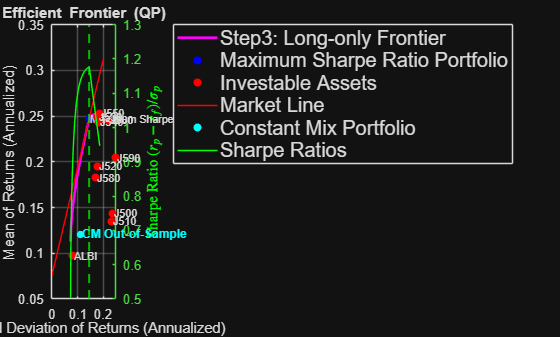

%10. Constant Mix Strategy on Test Dataset
% 10.1 Compute Constant Mix Out of Sample Portfolio statistics
function [ret, rsk] = constantMix(testReturnsTable, Wts, excludingTickers)
    testReturnsTable = testReturnsTable{:,excludingTickers};
    if size(testReturnsTable,1) == 1
        % If one row, 'mean' calculates the mean for the row, 
        % therefore skip it
        ret = testReturnsTable * Wts';
    else
        % If Multiple rows, 'mean' calculates the mean for the column
        % therefore use it
        ret = mean(testReturnsTable) * Wts';
    end
    rsk  = sqrt(Wts*cov(testReturnsTable)*Wts');
end
function [Sharpe] = sharpeRatio(ret, rsk, testReturnsTable, riskFreeTicker)
    ERFR = mean(testReturnsTable{:,riskFreeTicker});
    Sharpe = sqrt(12)*(ret-ERFR)./rsk;
end

% 10.2 Extract test returns (excluding cash and market indices)
testReturnsTable = tick2ret(test,'Method',returnType); % Change this if needed
[cmMean, cmSd] = constantMix(testReturnsTable,Wts_train, tickers);
[cmSharpe] = sharpeRatio(cmMean, cmSd,testReturnsTable, riskFreeTicker);

% 10.3 Plot
yyaxis left 
hold on
scatter(sqrt(12) * cmSd, 12 * cmMean, 30, 'c', 'filled','DisplayName', 'Constant Mix Portfolio'); 
text(sqrt(12) * cmSd+0.003, 12 * cmMean, 'CM Out-of-Sample', ...
     'FontSize', 9, 'Color', 'c', 'FontWeight', 'bold');
hold off

### Testing Buy-Hold Strategy

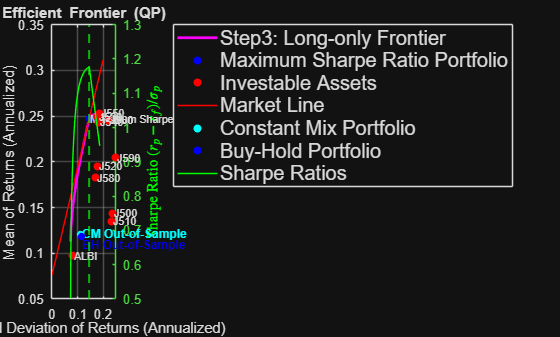

% 10.1 Buy hold strategy 
function [ret, rsk] = buyHold(testReturnsTable, Wts, includingTickers)
    % Exclude unwanted tickers
    R = testReturnsTable{:, includingTickers};
    [nPeriods, nAssets] = size(R);
    % Start with a notional portfolio value of 1 and allocate it based on initial weights
    assetValues = Wts; 
    portValues = zeros(nPeriods + 1, 1);
    portValues(1) = sum(assetValues); % Initial portfolio value is the sum of initial asset values
    for t = 1:nPeriods
        % Grow each asset by its return for the current period
        assetValues = assetValues .* (1+R(t, :)); % use exp(R(t,:)) if continuous returns
        % The portfolio value is the sum of the new asset values
        portValues(t+1) = sum(assetValues);
        portRetSeries(t) = (portValues(t+1) - portValues(t)) / portValues(t);
    end
    % Calculate the mean and standard deviation of returns
    ret = mean(portRetSeries);
    rsk = std(portRetSeries);
end
function [Sharpe] = sharpeRatioM2Y(ret, rsk, testReturnsTable, riskFreeTicker)
    % Takes in Monthly ret and rsk and outputs an annualised Year sharpe ratio
    ERFR = mean(testReturnsTable{:,riskFreeTicker});
    Sharpe = sqrt(12)*(ret-ERFR)./rsk;
end

% 10.2 Extract test returns (excluding cash and market indices)
testReturnsTable = tick2ret(test,'Method',returnType); % Change this if needed
[bhMean, bhSd] = buyHold(testReturnsTable,Wts_train, tickers);
[bhSharpe] = sharpeRatioM2Y(bhMean, bhSd,testReturnsTable, riskFreeTicker);

% 10.3 Plot
yyaxis left 
hold on
scatter(sqrt(12) * bhSd, bhMean*12, 30, 'b', 'filled','DisplayName', 'Buy-Hold Portfolio'); 
text(sqrt(12) * bhSd+0.003, bhMean*12-0.01, 'BH Out-of-Sample', ...
     'FontSize', 9, 'Color', 'b', 'FontWeight', 'bold');
hold off

### Tables for Results Comparison

% 11.1 In-sample statistics
inMean   = retSR;
inVar    = rskSR^2;
inSharpe = sharpeRatio(retSR, rskSR, trainReturnsTable, riskFreeTicker);

% 11.2 Comparison table
ResultsComparison = table( ...
    [inMean; cmMean; bhMean], ...
    [inVar;  cmSd^2; bhSd^2], ...
    [inSharpe; cmSharpe; bhSharpe], ...
    'VariableNames', {'Mean','Variance','SharpeRatio'}, ...
    'RowNames', {'In-Sample SR','Out-of-Sample CM','Out-of-Sample BH'});
disp(ResultsComparison);

                          Mean       Variance     SharpeRatio
                        _________    _________    ___________

    In-Sample SR         0.020594    0.0017584       1.1765  
    Out-of-Sample CM     0.010048    0.0010698       0.5486  
    Out-of-Sample BH    0.0098988    0.0010921      0.52736  




% 11.3 Portfolio weights table
tickersWithDesc = {...
    'ALBI-All-Bond','J500-Oil-Gas','J510-Basic-Materials','J520-Industrials','J530-Consumer-Goods','J540-Health-Care', ...
    'J550-Consumer-Services','J560-Telecommunication','J580-Financials','J590-Technology'};

% 11.3.1 Display table
WeightTable = array2table(round(Wts_train,4), 'VariableNames', tickersWithDesc);
disp(WeightTable);

    ALBI-All-Bond    J500-Oil-Gas    J510-Basic-Materials    J520-Industrials    J530-Consumer-Goods    J540-Health-Care    J550-Consumer-Services    J560-Telecommunication    J580-Financials    J590-Technology
    _____________    ____________    ____________________    ________________    ___________________    ________________    ______________________    ______________________    _______________    _______________

          0               0                   0                     0                  0.4041                0.3147                 0.1079                    0.1733                   0                  0       



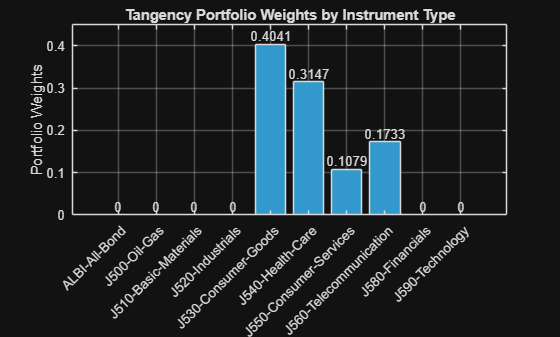


% 11.3.2 Bar plot of portfolio weights
figure;
bar(Wts_train, 'FaceColor',[0.2 0.6 0.8]); % blueish bars
xticks(1:length(tickersWithDesc));
xticklabels(tickersWithDesc);
xtickangle(45); % tilt labels for readability
ylabel('Portfolio Weights');
title('Tangency Portfolio Weights by Instrument Type');
% Add values on top of each bar
xPos = 1:length(Wts_train);
yPos = Wts_train;
labels = string(round(Wts_train,4)); % round to 4 decimals (adjust if needed)
text(xPos, yPos, labels, 'HorizontalAlignment','center', ...
     'VerticalAlignment','bottom', 'FontSize',10);
grid on;

### Additional Statistical Sophistication (Test/Training Split)

% 1. Parameters
splits = 0.1:0.05:0.9;  % training fraction
nObs = size(allDataTable,1);

% 2.1 Preallocate results
results = table('Size',[length(splits),10], ...
                'VariableTypes',{'double','double','double','double','double','double','double','double','double','double'}, ...
                'VariableNames',{'TrainFraction','InReturn','InVar','InSharpe','OutCMReturn','OutCMVar','OutCMSharpe','OutBHReturn','OutBHVar','OutBHSharpe'});
% 2.2 Preallocate weight table
tickersWithDesc = {...
    'TrainFraction','ALBI-All-Bond','J500-Oil-Gas','J510-Basic-Materials','J520-Industrials','J530-Consumer-Goods','J540-Health-Care', ...
    'J550-Consumer-Services','J560-Telecommunication','J580-Financials','J590-Technology'};
weightsTable = array2table(NaN(length(splits), length(tickers)+1), ...
                           'VariableNames', tickersWithDesc);

% 3. Loop over training/test splits
for i = 1:length(splits)
    trainFrac = splits(i);
    splitPoint = floor(trainFrac * nObs);
    
    % 3.1 Split data
    train = allDataTable(1:splitPoint,:);
    test  = allDataTable(splitPoint+1:end,:);
    
    % 3.2 Compute returns
    trainReturnsTable = tick2ret(train,'Method',returnType);
    testReturnsTable = tick2ret(test,'Method',returnType);
    
    % 3.3 Max Sharpe Tangency Portfolio on training set
    [Wts_train,retSR,rskSR,ERFR_Train] = maxSharpeRatio(trainReturnsTable, tickers, riskFreeTicker);
    
    % 3.4 Store training weights
    weightsTable{i,:} = [trainFrac, Wts_train];
    
    % 3.5 Compute in-sample Sharpe, return, variance
    inRet = retSR;
    inVar = rskSR^2;
    inSharpe = sharpeRatio(retSR, rskSR, trainReturnsTable, riskFreeTicker);
    
    % 3.6 Implement CM on test set
    [cmMean, cmSd] = constantMix(testReturnsTable,Wts_train,tickers);
    outCMRet = cmMean;
    outCMVar = cmSd^2;
    outCMSharpe = sharpeRatio(cmMean, cmSd, testReturnsTable, riskFreeTicker);
    
    % 3.6 Implement CM on test set
    [bhMean, bhSd] = buyHold(testReturnsTable,Wts_train,tickers);
    outBHRet = bhMean;
    outBHVar = bhSd^2;
    outBHSharpe = sharpeRatio(bhMean, bhSd, testReturnsTable, riskFreeTicker);

    % 3.7 Store results
    results.TrainFraction(i) = trainFrac;
    results.InReturn(i) = inRet;
    results.InVar(i) = inVar;
    results.InSharpe(i) = inSharpe;
    results.OutCMReturn(i) = outCMRet;
    results.OutCMVar(i) = outCMVar;
    results.OutCMSharpe(i) = outCMSharpe;
    results.OutBHReturn(i) = outBHRet;
    results.OutBHVar(i) = outBHVar;
    results.OutBHSharpe(i) = outBHSharpe;
end

% 4. Display results table
disp(results);

    TrainFraction    InReturn      InVar       InSharpe    OutCMReturn     OutCMVar     OutCMSharpe    OutBHReturn     OutBHVar     OutBHSharpe
    _____________    ________    __________    ________    ___________    __________    ___________    ___________    __________    ___________

         0.1         0.034573    0.00058255      3.978       0.014907      0.0025201       0.62871       0.014974      0.0025143       0.63407 
        0.15          0.03282     0.0011788     2.6539       0.012203      0.0018784       0.51218       0.012122      0.0018846       0.50486 
         0.2         0.033571     0.0012412     2.6833       0.009882      0.001902


% 5. Display weights table
disp(weightsTable);

    TrainFraction    ALBI-All-Bond    J500-Oil-Gas    J510-Basic-Materials    J520-Industrials    J530-Consumer-Goods    J540-Health-Care    J550-Consumer-Services    J560-Telecommunication    J580-Financials    J590-Technology
    _____________    _____________    ____________    ____________________    ________________    ___________________    ________________    ______________________    ______________________    _______________    _______________

         0.1           1.677e-22       3.9156e-22            0.046633            1.2996e-22              0.04344               0.90993             2.2204e-16            

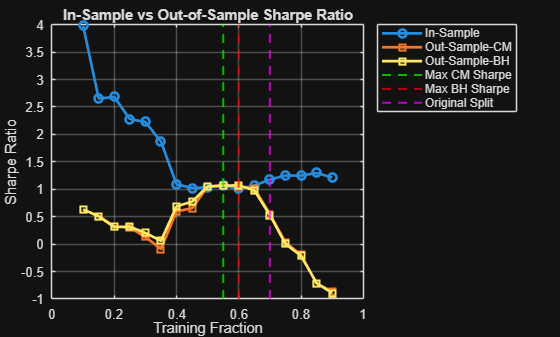


% 6. Plot Sharpe Ratio
figure;
plot(results.TrainFraction, results.InSharpe, '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, results.OutCMSharpe, '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
plot(results.TrainFraction, results.OutBHSharpe, '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
% Find indices of maximum Sharpe ratios
[~, idxCM] = max(results.OutCMSharpe);
[~, idxBH] = max(results.OutBHSharpe);
% Add vertical lines at maximum Sharpe ratio points
xline(results.TrainFraction(idxCM), '--g', 'LineWidth',1.5, 'DisplayName','Max CM Sharpe');
xline(results.TrainFraction(idxBH), '--r', 'LineWidth',1.5, 'DisplayName','Max BH Sharpe');
xline(0.7, '--m', 'LineWidth',1.5, 'DisplayName','Original Split');
xlabel('Training Fraction');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio');
legend({'In-Sample','Out-Sample-CM','Out-Sample-BH','Max CM Sharpe','Max BH Sharpe','Original Split'},'Location','northeastoutside');
grid on;
hold off;

% Select the three training splits
selectedSplits = weightsTable(ismember(weightsTable.TrainFraction, [0.7, 0.55, 0.6]), :);
disp(selectedSplits)

    TrainFraction    ALBI-All-Bond    J500-Oil-Gas    J510-Basic-Materials    J520-Industrials    J530-Consumer-Goods    J540-Health-Care    J550-Consumer-Services    J560-Telecommunication    J580-Financials    J590-Technology
    _____________    _____________    ____________    ____________________    ________________    ___________________    ________________    ______________________    ______________________    _______________    _______________

        0.55          2.1009e-16       1.5371e-17          2.0166e-16            1.3258e-17             0.35822              0.20802                0.21999              

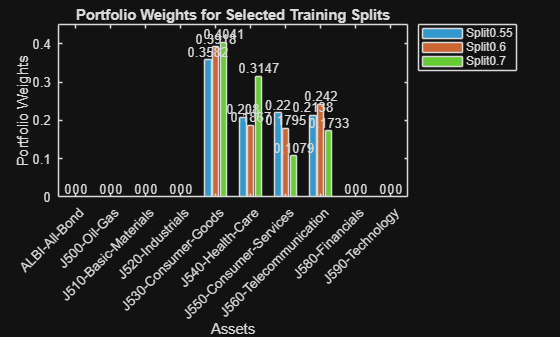

% Extract weights as a matrix (rows = splits, columns = assets)
weightsMatrix = selectedSplits{:, 2:end};  % remove TrainFraction column
% Assets and number of splits
assets = selectedSplits.Properties.VariableNames(2:end);
numAssets = length(assets);
numSplits = height(selectedSplits);
% Create grouped bar chart
figure;
b = bar(weightsMatrix', 'grouped');  % transpose so assets on x-axis
% Customize colors (optional)
colors = [0.2 0.6 0.8; 0.8 0.4 0.2; 0.4 0.8 0.2]; % one color per split
for i = 1:numSplits
    b(i).FaceColor = colors(i,:);
end
% Set x-axis labels
xticks(1:numAssets);
xticklabels(assets);
xtickangle(45);
ylabel('Portfolio Weights');
xlabel('Assets');
title('Portfolio Weights for Selected Training Splits');
legend(strcat('Split ', string(selectedSplits.TrainFraction)), 'Location', 'northeastoutside');
hold on;
% Add values on top of each bar
for i = 1:numSplits
    x = b(i).XEndPoints;       % x positions of bars
    y = b(i).YEndPoints;       % heights of bars
    labels = string(round(weightsMatrix(i,:),4));
    text(x, y, labels, 'HorizontalAlignment','center', 'VerticalAlignment','bottom', 'FontSize',10);
end
hold off;


% Show sharpe ratios of maximum 
% Define target training fractions
targetSplits = [0.7, 0.55, 0.6];
% Find the rows corresponding to those splits
rows = ismember(results.TrainFraction, targetSplits);
% Create table
SharpeTable = table(...
    results.TrainFraction(rows), ...
    results.InSharpe(rows), ...
    results.OutCMSharpe(rows), ...
    results.OutBHSharpe(rows), ...
    'VariableNames', {'TrainFraction', 'InSampleSharpe', 'OutCMSharpe', 'OutBHSharpe'});
% Display the table
disp(SharpeTable);

    TrainFraction    InSampleSharpe    OutCMSharpe    OutBHSharpe
    _____________    ______________    ___________    ___________

        0.55             1.0646          1.0764          1.0653  
         0.6             1.0081          1.0561          1.0707  
         0.7             1.1765          0.5486         0.52736  



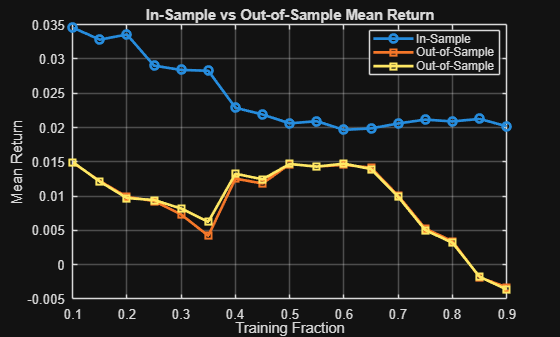


% 7. Plot Mean Return vs Training Fraction
figure;
plot(results.TrainFraction, results.InReturn, '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, results.OutCMReturn, '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
plot(results.TrainFraction, results.OutBHReturn, '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
xlabel('Training Fraction');
ylabel('Mean Return');
title('In-Sample vs Out-of-Sample Mean Return');
legend('Location','best');
grid on;
hold off;

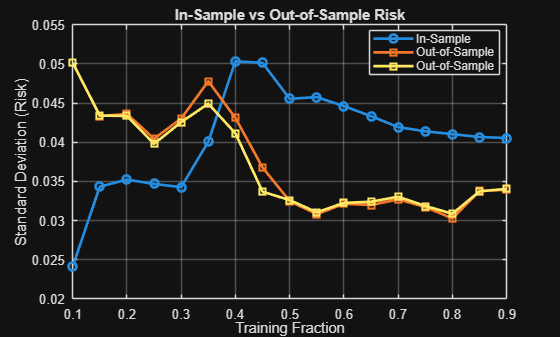


% 8. Plot Standard Deviation vs Training Fraction
figure;
plot(results.TrainFraction, sqrt(results.InVar), '-o', 'LineWidth',2, 'DisplayName','In-Sample');
hold on;
plot(results.TrainFraction, sqrt(results.OutCMVar), '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
plot(results.TrainFraction, sqrt(results.OutBHVar), '-s', 'LineWidth',2, 'DisplayName','Out-of-Sample');
xlabel('Training Fraction');
ylabel('Standard Deviation (Risk)');
title('In-Sample vs Out-of-Sample Risk');
legend('Location','best');
grid on;
hold off;

## Experiment 2

### Set-up

tickers = setdiff(allDataTable.Properties.VariableNames, ...
    {'STEFI','JIBAR','ALSI','J330','J331'});  % Excluded Tickers
returnType = 'continuous';
riskFreeRate = 'STEFI';

### Time Series


% 1. Parameters
windowFrac = 0.3;                                % training fraction of total data
nObs = size(allDataTable,1);                     % total months
windowSize = floor(windowFrac * nObs);           % training window size in months

% 2. Preallocate result time series
nSteps = nObs - windowSize;
CMresults = table('Size',[nSteps,7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'CM_InReturn','CM_InVar','CM_InSharpe','CM_OutReturn','CM_OutVar','CM_OutSharpe','CM_SharpeDiff'});
RWresults = table('Size',[nSteps,7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'RW_InReturn','RW_InVar','RW_InSharpe','RW_OutReturn','RW_OutVar','RW_OutSharpe','RW_SharpeDiff'});
BHresults = table('Size',[nSteps,7], ...
    'VariableTypes',{'double','double','double','double','double','double','double'}, ...
    'VariableNames',{'BH_InReturn','BH_InVar','BH_InSharpe','BH_OutReturn','BH_OutVar','BH_OutSharpe','BH_SharpeDiff'});

% Preallocate tables for weights and test month
CM_WeightsTable = table('Size',[nSteps, length(tickers)+1], ...
                        'VariableTypes',[ "datetime", repmat("double",1,length(tickers)) ], ...
                        'VariableNames', [{'TestMonth'}, tickers]);
RW_WeightsTable = table('Size',[nSteps, length(tickers)+1], ...
                        'VariableTypes',[ "datetime", repmat("double",1,length(tickers)) ], ...
                        'VariableNames', [{'TestMonth'}, tickers]);
BH_WeightsTable = table('Size',[nSteps, length(tickers)+1], ...
                        'VariableTypes',[ "datetime", repmat("double",1,length(tickers)) ], ...
                        'VariableNames', [{'TestMonth'}, tickers]);


% 3. CM weights (fixed from first window)
train_CM = allDataTable(1:windowSize,:);
trainReturns_CMBH = tick2ret(train_CM,'Method',returnType);
[Wts_CMBH,retSR_CMBH,rskSR_CMBH,~] = maxSharpeRatio(trainReturns_CMBH, tickers, riskFreeRate);

% 4. Store in-sample Sharpe for CM
inSharpeCMBH = sharpeRatio(retSR_CMBH, rskSR_CMBH, trainReturns_CMBH, riskFreeRate);

% Buy hold set up
assetValues = Wts_CMBH; 
portValues = zeros(nSteps + 1, 1); 
portValues(1) = sum(assetValues);
portRetSeries = zeros(nSteps, 1);

% Preallocate vectors to store one-month test returns for each strategy
CM_portRetSeries = zeros(nSteps,1);  % Constant Mix
RW_portRetSeries = zeros(nSteps,1);  % Rolling Window

% 5. Loop for both RW and CM time-series
for t = 1:nSteps
    % 5.1 Rolling Window Training 
    train_RW = allDataTable(t:(t+windowSize-1),:);
    trainReturns_RW = tick2ret(train_RW,'Method',returnType);
    
    [Wts_RW,retSR_RW,rskSR_RW,~] = maxSharpeRatio(trainReturns_RW, tickers, riskFreeRate);
    inSharpeRW = sharpeRatio(retSR_RW, rskSR_RW, trainReturns_RW, riskFreeRate);
    
    % 5.2 Test month (same for CM and RW) 
    testRow = [train_RW(end,:); allDataTable(t+windowSize,:)];  % one month forward
    testReturns = tick2ret(testRow,'Method',returnType);
    
    % 5.3 CM fixed weights (balancing)
    [cmMean, ~] = constantMix(testReturns, Wts_CMBH, tickers);
    CM_portRetSeries(t) = cmMean;
    cmSd = std(CM_portRetSeries);
    CMresults.CM_InReturn(t) = retSR_CMBH;
    CMresults.CM_InVar(t) = rskSR_CMBH^2;
    CMresults.CM_InSharpe(t) = inSharpeCMBH;
    CMresults.CM_OutReturn(t) = cmMean;
    CMresults.CM_OutVar(t) = cmSd^2;
    CMresults.CM_OutSharpe(t) = sharpeRatio(cmMean, cmSd, testReturns, riskFreeTicker);
    CMresults.CM_SharpeDiff(t) =abs(sharpeRatio(cmMean, cmSd, testReturns, riskFreeTicker) -inSharpeCMBH);
    CM_WeightsTable.TestMonth(t) = allDataTable.Time(t+windowSize); 
    CM_WeightsTable{t, 2:end} = Wts_CMBH;

    % BH fixed weights (No rebalancing)
    % Use exp(returns) if continuous
    assetValues = assetValues .* exp(testReturns{:, tickers});
    portValues(t+1) = sum(assetValues);
    portRetSeries(t) = (portValues(t+1) - portValues(t)) / portValues(t);
    BHresults.BH_InReturn(t) = retSR_CMBH;
    BHresults.BH_InVar(t) = rskSR_CMBH^2;
    BHresults.BH_InSharpe(t) = inSharpeCMBH;
    BHresults.BH_OutReturn(t) = mean(portRetSeries);
    BHresults.BH_OutVar(t) = std(portRetSeries)^2;
    BHresults.BH_OutSharpe(t) = sharpeRatioM2Y(mean(portRetSeries), std(portRetSeries), testReturns, riskFreeTicker);
    BHresults.BH_SharpeDiff(t) =abs(sharpeRatioM2Y(mean(portRetSeries), std(portRetSeries), testReturns, riskFreeTicker) -inSharpeCMBH);
    BH_WeightsTable.TestMonth(t) = allDataTable.Time(t+windowSize);
    BH_WeightsTable{t, 2:end} = assetValues./sum(assetValues);

    % 5.4 Rolling Window updated weights 
    [rwMean, ~] = constantMix(testReturns, Wts_RW, tickers);
    RW_portRetSeries(t) = rwMean;
    rwSd = std(RW_portRetSeries);
    RWresults.RW_InReturn(t) = retSR_RW;
    RWresults.RW_InVar(t) = rskSR_RW^2;
    RWresults.RW_InSharpe(t) = inSharpeRW;
    RWresults.RW_OutReturn(t) = rwMean;
    RWresults.RW_OutVar(t) = rwSd^2;
    RWresults.RW_OutSharpe(t) = sharpeRatio(rwMean, rwSd, testReturns, riskFreeTicker);
    RWresults.RW_SharpeDiff(t) = abs(sharpeRatio(rwMean, rwSd, testReturns, riskFreeTicker) -inSharpeRW); 
    RW_WeightsTable.TestMonth(t) = allDataTable.Time(t+windowSize);
    RW_WeightsTable{t, 2:end} = Wts_RW;
end

%disp(CMresults)
%disp(RWresults)
%disp(BHresults)

### Results

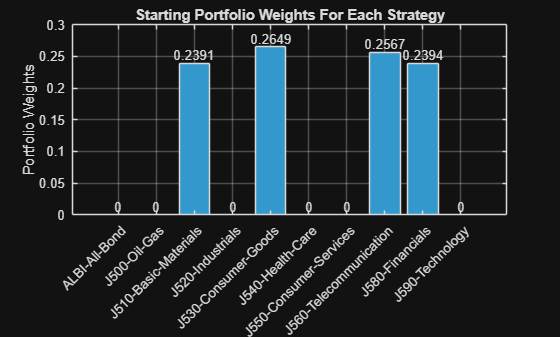

% Initial Weights for CM and BH
tickersWithDesc = {...
    'ALBI-All-Bond','J500-Oil-Gas','J510-Basic-Materials','J520-Industrials','J530-Consumer-Goods','J540-Health-Care', ...
    'J550-Consumer-Services','J560-Telecommunication','J580-Financials','J590-Technology'};
figure;
bar(Wts_CMBH, 'FaceColor',[0.2 0.6 0.8]); % blueish bars
xticks(1:length(tickersWithDesc));
xticklabels(tickersWithDesc);
xtickangle(45); % tilt labels for readability
ylabel('Portfolio Weights');
title('Starting Portfolio Weights For Each Strategy');
% Add values on top of each bar
xPos = 1:length(Wts_CMBH);
yPos = Wts_CMBH;
labels = string(round(Wts_CMBH,4)); % round to 4 decimals
text(xPos, yPos, labels, 'HorizontalAlignment','center', ...
     'VerticalAlignment','bottom', 'FontSize',10);
grid on;

disp(Wts_CMBH)

    0.0000    0.0000    0.2391    0.0000    0.2649    0.0000    0.0000    0.2567    0.2394    0.0000



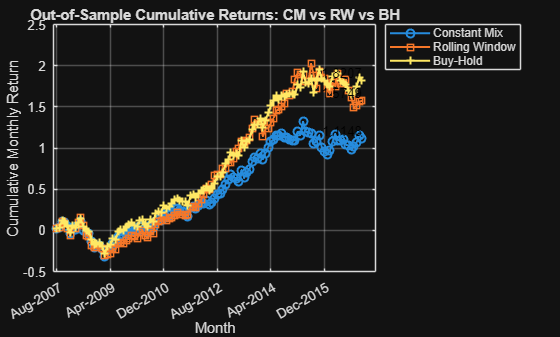



% 6. Time-Series of Strategy Performance (Out-of-Sample)
% 6.1 Compute cumulative returns
cumCM = cumprod(1 + CMresults.CM_OutReturn) - 1;
cumRW = cumprod(1 + RWresults.RW_OutReturn) - 1;
cumBH = cumprod(1 + portRetSeries) - 1;
% 6.2 Plot
% Assume your allDataTable has a datetime column called 'Date'
dates = allDataTable.Time(windowSize+1:end); % test period dates
nSteps = length(dates);
% Indices for tick labels (every 20th month)
tickStep = 20;
tickIdx = 1:tickStep:nSteps;
% Plot cumulative returns
% 6.2 Plot with final cumulative returns
figure;
hCM = plot(1:nSteps, cumCM, '-o', 'LineWidth',1.5);
hold on;
hRW = plot(1:nSteps, cumRW, '-s', 'LineWidth',1.5);
hBH = plot(1:nSteps, cumBH, '-+', 'LineWidth',1.5);
% Set x-axis labels as dates for every 20th month
xticks(tickIdx);
xticklabels(datestr(dates(tickIdx), 'mmm-yyyy')); % format as "Aug-2003"
xlabel('Month');
ylabel('Cumulative Monthly Return');
title('Out-of-Sample Cumulative Returns: CM vs RW vs BH');
% Annotate final cumulative return at end of each line
text(nSteps, cumCM(end), sprintf('%.4f', cumCM(end)), 'VerticalAlignment','bottom','HorizontalAlignment','right', 'Color', 'k');
text(nSteps, cumRW(end), sprintf('%.4f', cumRW(end)), 'VerticalAlignment','bottom','HorizontalAlignment','right', 'Color', 'k');
text(nSteps, cumBH(end), sprintf('%.4f', cumBH(end)), 'VerticalAlignment','bottom','HorizontalAlignment','right', 'Color', 'k');
legend('Constant Mix','Rolling Window', 'Buy-Hold','Location', 'northeastoutside');
grid on;
hold off;

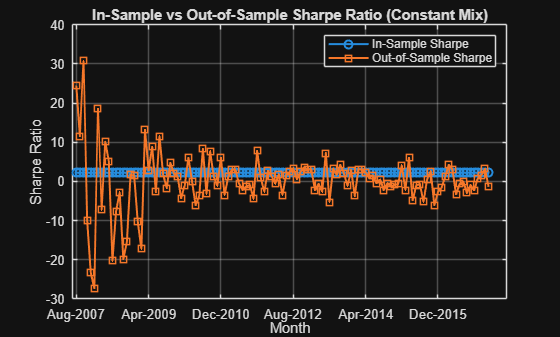



% 7. Compare In-Sample Sharpe Ratios vs Out-of-Sample CM Sharpe
figure;
plot(1:nSteps, CMresults.CM_InSharpe, '-o','LineWidth',1.5);
hold on;
plot(1:nSteps, CMresults.CM_OutSharpe, '-s','LineWidth',1.5);
xticks(tickIdx);
xticklabels(datestr(dates(tickIdx), 'mmm-yyyy')); % format as "Aug-2003"
xlabel('Month');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio (Constant Mix)');
legend('In-Sample Sharpe','Out-of-Sample Sharpe');
grid on;
hold off;

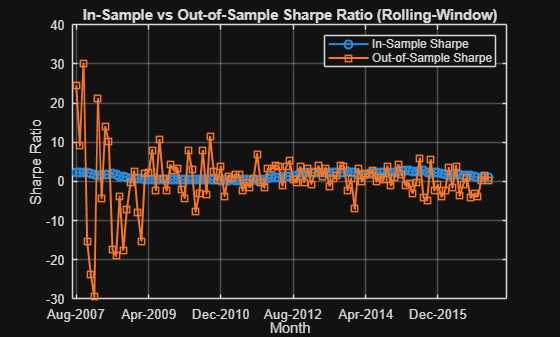


% 8. Compare In-Sample vs Out-of-Sample Sharpe for Rolling-Window
figure;
plot(1:nSteps, RWresults.RW_InSharpe, '-o', 'LineWidth', 1.5);
hold on;
plot(1:nSteps, RWresults.RW_OutSharpe, '-s', 'LineWidth', 1.5);
xticks(tickIdx);
xticklabels(datestr(dates(tickIdx), 'mmm-yyyy')); % format as "Aug-2003"
xlabel('Month');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio (Rolling-Window)');
legend('In-Sample Sharpe', 'Out-of-Sample Sharpe');
grid on;
hold off;

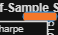

% 8. Compare In-Sample vs Out-of-Sample Sharpe for Buy-hold
figure;
plot(3:nSteps, BHresults.BH_InSharpe(3:end), '-o', 'LineWidth', 1.5);
hold on;
plot(3:nSteps, BHresults.BH_OutSharpe(3:end), '-s', 'LineWidth', 1.5);
xticks(tickIdx);
xticklabels(datestr(dates(tickIdx), 'mmm-yyyy')); % format as "Aug-2003"
xlabel('Month');
ylabel('Sharpe Ratio');
title('In-Sample vs Out-of-Sample Sharpe Ratio (Buy-Hold)');
legend('In-Sample Sharpe', 'Out-of-Sample Sharpe');
grid on;
hold off;


% 9.  Table of Portfolio Statistics (two columns: CM and RW)
stats = {'MeanReturn'; 'Variance'; 'Sharpe'; 'MinReturn'; 'MaxReturn'; 'MinSharpe'; 'MaxSharpe';'Cumulative Return'};
% 9.1 CM statistics vector
CMstats = [ ...
    mean(CMresults.CM_OutReturn); ...
    mean(CMresults.CM_OutVar); ...
    mean(CMresults.CM_OutSharpe); ...
    min(CMresults.CM_OutReturn); ...
    max(CMresults.CM_OutReturn); ...
    min(CMresults.CM_OutSharpe); ...
    max(CMresults.CM_OutSharpe); ...
    cumCM(end)...
];
% 9.2 RW statistics vector
RWstats = [ ...
    mean(RWresults.RW_OutReturn); ...
    mean(RWresults.RW_OutVar); ...
    mean(RWresults.RW_OutSharpe); ...
    min(RWresults.RW_OutReturn); ...
    max(RWresults.RW_OutReturn); ...
    min(RWresults.RW_OutSharpe); ...
    max(RWresults.RW_OutSharpe); ...
    cumRW(end)...
];
% 9.2 RW statistics vector
BHstats = [ ...
    mean(BHresults.BH_OutReturn); ...
    mean(BHresults.BH_OutVar); ...
    mean(BHresults.BH_OutSharpe(3:end)); ...
    min(BHresults.BH_OutReturn); ...
    max(BHresults.BH_OutReturn); ...
    min(BHresults.BH_OutSharpe(3:end)); ...
    max(BHresults.BH_OutSharpe(3:end)); ...
    cumBH(end)...
];

% 9.3 Combine into a table
SummaryTable = table(CMstats, RWstats, BHstats,'RowNames', stats, 'VariableNames', {'ConstantMix','RollingWindow','BuyHold'});
% 9.4 Display
disp(SummaryTable);

                         ConstantMix    RollingWindow     BuyHold  
                         ___________    _____________    __________

    MeanReturn            0.0074458       0.0092435        0.004892
    Variance              0.0011948       0.0012727       0.0012038
    Sharpe                  0.17241         0.36312        -0.28952
    MinReturn              -0.11459        -0.11523      -0.0025444
    MaxReturn               0.11293         0.12251        0.010309
    MinSharpe               -27.332         -29.391         -3.3202
    MaxSharpe                30.809          30.106          0.8217
    Cumulative Return        1.1148          1.5749          1.8207



#### Weight plots

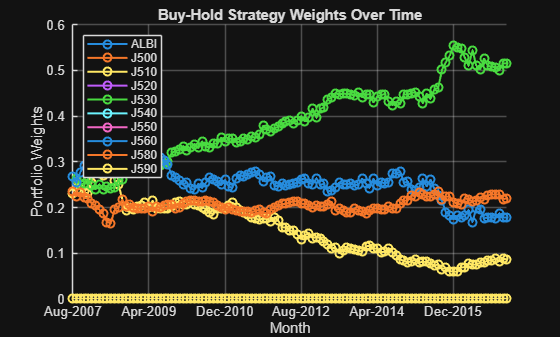

% Define the tick step for x-axis spacing
tickStep = 20;  

%% Buy-Hold Weights Plot
figure;
hold on;
for i = 2:width(BH_WeightsTable)  % skip first column (TestMonth)
    plot(BH_WeightsTable.TestMonth, BH_WeightsTable{:, i}, '-o', 'LineWidth', 1.5, 'DisplayName', BH_WeightsTable.Properties.VariableNames{i});
end
xticks(BH_WeightsTable.TestMonth(1:tickStep:end));
xticklabels(datestr(BH_WeightsTable.TestMonth(1:tickStep:end), 'mmm-yyyy'));
xlabel('Month');
ylabel('Portfolio Weights');
title('Buy-Hold Strategy Weights Over Time');
legend('Location','northwest');
grid on;
hold off;

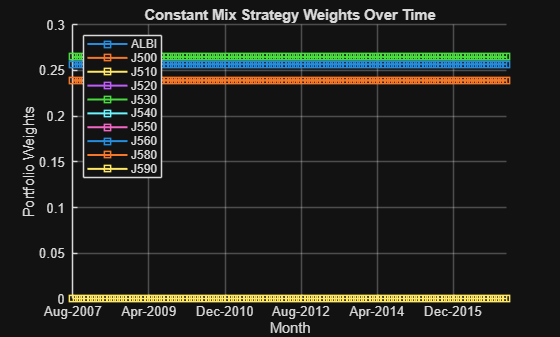


%% Constant Mix Weights Plot
figure;
hold on;
for i = 2:width(CM_WeightsTable)
    plot(CM_WeightsTable.TestMonth, CM_WeightsTable{:, i}, '-s', 'LineWidth', 1.5, 'DisplayName', CM_WeightsTable.Properties.VariableNames{i});
end
xticks(CM_WeightsTable.TestMonth(1:tickStep:end));
xticklabels(datestr(CM_WeightsTable.TestMonth(1:tickStep:end), 'mmm-yyyy'));
xlabel('Month');
ylabel('Portfolio Weights');
title('Constant Mix Strategy Weights Over Time');
legend('Location','northwest');
grid on;
hold off;

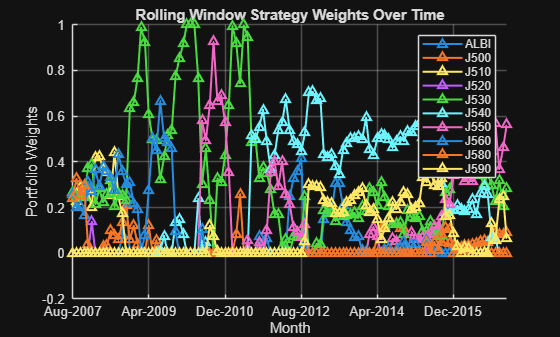


%% Rolling Window Weights Plot
figure;
hold on;
for i = 2:width(RW_WeightsTable)
    plot(RW_WeightsTable.TestMonth, RW_WeightsTable{:, i}, '-^', 'LineWidth', 1.5, 'DisplayName', RW_WeightsTable.Properties.VariableNames{i});
end
xticks(RW_WeightsTable.TestMonth(1:tickStep:end));
xticklabels(datestr(RW_WeightsTable.TestMonth(1:tickStep:end), 'mmm-yyyy'));
xlabel('Month');
ylabel('Portfolio Weights');
title('Rolling Window Strategy Weights Over Time');
legend('Location','northeast');
grid on;
hold off;


% Get asset names (skip TestMonth column)
assets = BH_WeightsTable.Properties.VariableNames(2:end);
% Extract initial weights (first row of BH table, could use any)
initialWeights = BH_WeightsTable{1, 2:end};
% Extract ending weights (last row of each table)
endingBH = BH_WeightsTable{end, 2:end};
endingCM = CM_WeightsTable{end, 2:end};
endingRW = RW_WeightsTable{end, 2:end};
% Create summary table
WeightsSummary = array2table([initialWeights; endingCM; endingBH; endingRW], ...
    'VariableNames', assets, ...
    'RowNames', {'Initial', 'End_CM', 'End_BH', 'End_RW'});
% Display the table
disp(WeightsSummary);

                  ALBI          J500          J510          J520        J530         J540          J550          J560          J580          J590   
               __________    __________    __________    __________    _______    __________    __________    __________    __________    __________

    Initial    2.1357e-16    2.1707e-17       0.23121    7.8226e-17    0.26711    8.9148e-17    2.1966e-17       0.26758        0.2341    1.1955e-16
    End_CM     2.1714e-16    2.0907e-17       0.23909    8.0398e-17    0.26485    8.9227e-17     2.236e-17        0.2567       0.23936    1.2154e-16
    End_BH  

### Additional Statistial Sophistication

% 1. Testing Window Fractions
windowFracs = 0.1:0.05:0.9;
nFracs = length(windowFracs);

% 2. Preallocate summary table
SummaryWindow = table('Size',[nFracs, 13], ...
    'VariableTypes', repmat("double",1,13), ...
    'VariableNames', {'WindowFrac', 'CM_MeanReturn','CM_Std','CM_Sharpe','CM_Cum','RW_MeanReturn','RW_Std','RW_Sharpe','RW_Cum','BH_MeanReturn','BH_Std','BH_Sharpe','BH_Cum'});

% 3. Loop
for w = 1:nFracs
    windowFrac = windowFracs(w);
    nObs = size(allDataTable,1);
    windowSize = floor(windowFrac * nObs);
    nSteps = nObs - windowSize;
   
    CMresults = table('Size',[nSteps,3], ...
        'VariableTypes',{'double','double','double'}, ...
        'VariableNames',{'CM_OutReturn','CM_OutVar','CM_OutSharpe'});
    RWresults = table('Size',[nSteps,3], ...
        'VariableTypes',{'double','double','double'}, ...
        'VariableNames',{'RW_OutReturn','RW_OutVar','RW_OutSharpe'});
    BHresults = table('Size',[nSteps,3], ...
        'VariableTypes',{'double','double','double'}, ...
        'VariableNames',{'BH_OutReturn','BH_OutVar','BH_OutSharpe'});
    
    % 3. CM weights (fixed from first window)
    train_CM = allDataTable(1:windowSize,:);
    trainReturns_CMBH = tick2ret(train_CM,'Method',returnType);
    [Wts_CMBH,retSR_CMBH,rskSR_CMBH,~] = maxSharpeRatio(trainReturns_CMBH, tickers, riskFreeRate);
    
    % 4. Store in-sample Sharpe for CM
    inSharpeCMBH = sharpeRatio(retSR_CMBH, rskSR_CMBH, trainReturns_CMBH, riskFreeRate);
    
    % Buy hold set up
    assetValues = Wts_CMBH; 
    portValues = zeros(nSteps + 1, 1); 
    portValues(1) = sum(assetValues);
    portRetSeries = zeros(nSteps, 1);
    
    % Preallocate vectors to store one-month test returns for each strategy
    CM_portRetSeries = zeros(nSteps,1);  % Constant Mix
    RW_portRetSeries = zeros(nSteps,1);  % Rolling Window
    
    % 5. Loop for both RW and CM time-series
    for t = 1:nSteps
        % 5.1 Rolling Window Training 
        train_RW = allDataTable(t:(t+windowSize-1),:);
        trainReturns_RW = tick2ret(train_RW,'Method',returnType);
        
        [Wts_RW,retSR_RW,rskSR_RW,~] = maxSharpeRatio(trainReturns_RW, tickers, riskFreeRate);
        inSharpeRW = sharpeRatio(retSR_RW, rskSR_RW, trainReturns_RW, riskFreeRate);
        
        % 5.2 Test month (same for CM and RW) 
        testRow = [train_RW(end,:); allDataTable(t+windowSize,:)];  % one month forward
        testReturns = tick2ret(testRow,'Method',returnType);
        
        % 5.3 CM fixed weights (balancing)
        [cmMean, ~] = constantMix(testReturns, Wts_CMBH, tickers);
        CM_portRetSeries(t) = cmMean;
        cmSd = std(CM_portRetSeries);
        CMresults.CM_OutReturn(t) = cmMean;
        CMresults.CM_OutVar(t) = cmSd^2;
        CMresults.CM_OutSharpe(t) = sharpeRatio(cmMean, cmSd, testReturns, riskFreeTicker);
    
        % BH fixed weights (No rebalancing)
        % Use exp(returns) if continuous
        assetValues = assetValues .* (1+testReturns{:,tickers});
        portValues(t+1) = sum(assetValues);
        portRetSeries(t) = (portValues(t+1) - portValues(t)) / portValues(t);
        BHresults.BH_OutReturn(t) = mean(portRetSeries);
        BHresults.BH_OutVar(t) = std(portRetSeries)^2;
        BHresults.BH_OutSharpe(t) = sharpeRatioM2Y(mean(portRetSeries), std(portRetSeries), testReturns, riskFreeTicker);
    
        % 5.4 Rolling Window updated weights 
        [rwMean, ~] = constantMix(testReturns, Wts_RW, tickers);
        RW_portRetSeries(t) = rwMean;
        rwSd = std(RW_portRetSeries);
        RWresults.RW_OutReturn(t) = rwMean;
        RWresults.RW_OutVar(t) = rwSd^2;
        RWresults.RW_OutSharpe(t) = sharpeRatio(rwMean, rwSd, testReturns, riskFreeTicker); 
    end
    % Compute cumulative returns
    cumCM = cumprod(1 + CMresults.CM_OutReturn) - 1;
    cumRW = cumprod(1 + RWresults.RW_OutReturn) - 1;
    cumBH = cumprod(1 + BHresults.BH_OutReturn) - 1;

    % 3.3.5 Store summary metrics in the windowFrac table 
    SummaryWindow.WindowFrac(w)    = windowFrac;
    SummaryWindow.CM_MeanReturn(w) = mean(CMresults.CM_OutReturn);
    SummaryWindow.CM_Std(w)        = sqrt(mean(CMresults.CM_OutVar));
    SummaryWindow.CM_Sharpe(w)     = mean(CMresults.CM_OutSharpe);
    SummaryWindow.CM_Cum(w)        = cumCM(end);
    SummaryWindow.RW_MeanReturn(w) = mean(RWresults.RW_OutReturn);
    SummaryWindow.RW_Std(w)        = sqrt(mean(RWresults.RW_OutVar));
    SummaryWindow.RW_Sharpe(w)     = mean(RWresults.RW_OutSharpe);
    SummaryWindow.RW_Cum(w)        = cumRW(end);
    SummaryWindow.BH_MeanReturn(w) = mean(BHresults.BH_OutReturn);
    SummaryWindow.BH_Std(w)        = sqrt(mean(BHresults.BH_OutVar));
    SummaryWindow.BH_Sharpe(w)     = mean(BHresults.BH_OutSharpe(3:end));
    SummaryWindow.BH_Cum(w)        = cumBH(end);
end

% 4. Display results
disp(SummaryWindow);

    WindowFrac    CM_MeanReturn     CM_Std     CM_Sharpe     CM_Cum      RW_MeanReturn     RW_Std     RW_Sharpe     RW_Cum      BH_MeanReturn     BH_Std     BH_Sharpe     BH_Cum  
    __________    _____________    ________    _________    _________    _____________    ________    _________    _________    _____________    ________    _________    _________

        0.1           0.014803     0.038841     -4.0886        6.2382      0.0081007      0.036311     -4.5092        1.7632      0.0085872      0.038474    -0.020059       2.5081
       0.15      

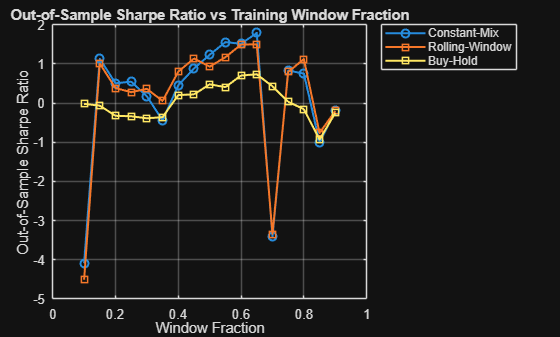

% 5. Plot Sharpe Ratio vs Window Fraction
figure;
plot(SummaryWindow.WindowFrac, SummaryWindow.CM_Sharpe, '-o', 'LineWidth', 1.5);
hold on;
plot(SummaryWindow.WindowFrac, SummaryWindow.RW_Sharpe, '-s', 'LineWidth', 1.5);
plot(SummaryWindow.WindowFrac, SummaryWindow.BH_Sharpe, '-s', 'LineWidth', 1.5);
xlabel('Window Fraction');
ylabel('Out-of-Sample Sharpe Ratio');
title('Out-of-Sample Sharpe Ratio vs Training Window Fraction');
legend('Constant-Mix', 'Rolling-Window','Buy-Hold', 'Location','northeastoutside');
grid on;
hold off;

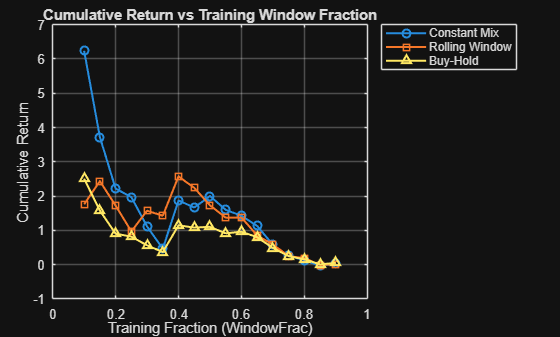


% 6. Cumulative Plot
% Extract the relevant data
windowFrac = SummaryWindow.WindowFrac;
cumCM = SummaryWindow.CM_Cum;
cumRW = SummaryWindow.RW_Cum;
cumBH = SummaryWindow.BH_Cum;
% Create the plot
figure;
plot(windowFrac, cumCM, '-o', 'LineWidth',1.5, 'DisplayName','Constant Mix');
hold on;
plot(windowFrac, cumRW, '-s', 'LineWidth',1.5, 'DisplayName','Rolling Window');
plot(windowFrac, cumBH, '-^', 'LineWidth',1.5, 'DisplayName','Buy-Hold');
xlabel('Training Fraction (WindowFrac)');
ylabel('Cumulative Return');
title('Cumulative Return vs Training Window Fraction');
legend('Location','northeastoutside');
grid on;
hold off;